## NDVI POR AÑO Y ESTACION

### del año 2000 al 2022

### 1.- Inicialización de la información

Imports y declaración de variables

import matlab.io.hdfeos.*

clearvars -except area_estudio;
close all;

Declaracón de variables como directorio de datos, latitud y longitud del área de estudio y posición en las cuadriculas de MODIS. 

declaraciones

>>> Declarando variables...ok



% Los años que se desean consultar
estaciones = 1:4;
anios = 2000:2022;

Variables para realizar seguimiento del código y mostrar más mensajes y/o mapas. Tiempo de pausa en segundos.

debug_pausa = 2; %tiempo de pausa de imagenes
debug_dibujar_mapa = false;  %dibujar los mapas 

Leer todos los archivos de la zona de estudio y guardar la información en una tabla

| idx | diaj | dia | mes | estación | año | v6 | v7 | calidad |

%% obtener la info del área de estudio
[lat,lon,ndvi] = m_leer_dir_hdfs(dir_data,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

>>>>> Obteniendo la zona de estudio
>>>>> Analizando 2 archivos


info_hdf = m_infohdfs2table(dir_data);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1042 archivos


Matriz que delimita el área de estudio. Se carga de archivo "area_estudio.mat". Sino existe. Lo crea. El proceso puede tardar un rato

ae = exist("area_estudio","var");
if ae == 0
    ae = exist("area_estudio.mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load area_estudio;
    else
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
        
    end
else
    if( numel(area_estudio) <= 1)
        disp("La variable area_estudio sera sustituida");
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
    end
end

>>> Cargando área de estudio


Pixeles en total del área de estudio

calidad_total = sum(area_estudio,"all");

Dibujar mapa de prueba de lectura de datos

% if debug_dibujar_mapa == true
%     ndvi(area_estudio==false)=NaN;
%     m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI TEST",[],ndvi_colormap,"NDVI");
%     m_dibujar_kml(dir_data,"RH26",1,'b',"RH26")
%     pause(debug_pausa);
% end 

### 2.- Declarar variables para obtener la información por estación

% Arreglo donde se almacenara el promedio de NDVI por año
tabla_promedio =zeros(length(anios),length(estaciones));
tabla_desvEst =zeros(length(anios),length(estaciones));

% Arreglo en 3d
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,length(anios) *length(estaciones));

%generar las etiquetas de año y estación
lbl_estaciones = ["Primavera","Verano","Otoño","Invierno"];

lbl_ejex = string(1: length(anios)*length(estaciones));

a=1;
for i=anios
    for j=estaciones
        lbl_ejex (a) = strcat( lbl_estaciones(j)," ",""+i);
        a=a+1;
    end
end

### 3.- Recuperar la información y crear las matrices de 3 dimensiones

Recuperar  la información

x=1;   
bp=waitbar(0,'Obteniendo información'); 

for y= 1:length(anios)
    waitbar(y/length(anios),bp);

    for a = 1:length(estaciones)
            tmp =  find(  info_hdf.anio == anios(y) & info_hdf.estacion == estaciones(a)  );
            img_fechas_consulta = info_hdf(tmp,:);
            [filas,~] = size(img_fechas_consulta);
            %disp("Estación: "+estaciones(a) +". No de archivos: "+filas);
            
            %arreglo de promedios de las imagenes
            arr_promedio_ae = zeros(1,filas);
            arr_ndvi_ae  = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);
            
            % obtener la info de un año
    
            for i=1:filas
    
                %disp("Analizando "+i+" de "+filas);
                [ndvi,~,~,disponibilidad] = m_obtener_ndvi(dir_data,img_fechas_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);
            
                % recortar el area de estudio
                ndvi(area_estudio==false)=NaN;
                disponibilidad(area_estudio==false)=NaN;
    
                %omitir las zonas con nubes o nieve
                ndvi (disponibilidad>1)=NaN;
                disponibilidad(disponibilidad>1)=NaN;
            
                calidad = m_calidad_imagen(disponibilidad,calidad_total);
            
                % promedio ndvi si es de buena calidad, sino nan
                if calidad >=95
                    arr_promedio_ae(i) = mean(ndvi,'all','omitnan');
                    arr_ndvi_ae(:,:,i) = ndvi;
                else
                    arr_promedio_ae(i) = nan;
                    arr_ndvi_ae(:,:,i) = nan;
                end
       
            end
    
        tabla_promedio(y,a) = mean(arr_promedio_ae,"all","omitnan");
        tabla_desvEst(y,a) = std(arr_promedio_ae,0,"all","omitnan");
    
    
        arr_ndvi(:,:,x) = m_mean_3dpp(arr_ndvi_ae);
    
        if debug_dibujar_mapa == true 
            % dibujar el mapa
            m_dibujar_mapa_ndvi(lon_mapa,lat_mapa,lon,lat,arr_ndvi(:,:,x),"NDVI promedio de "+lbl_ejex(x),0);
            pause (debug_pausa);
            
        end
        x=x+1;
    end
end
close(bp); 


### 4.- Usar los datos obtenidos 

Mostrar el promedio por estación de cada año

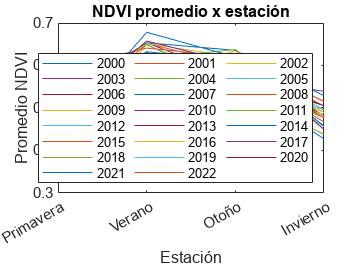

figure;

plot(tabla_promedio');
title('NDVI promedio x estación');
xlabel('Estación');
xticks(1:4);
xticklabels(lbl_estaciones);
ylabel('Promedio NDVI');
xlim([1 4]);
ylim([0.3 0.7]);

lgd=legend(string(anios),'Location','south','Orientation','horizontal');
lgd.NumColumns = 3;

exportgraphics(gca,"img/g_promedio_x_año_estacion.png",'Resolution',300) 

Mostrar la linea de tiempo de las estaciones a traves de los años

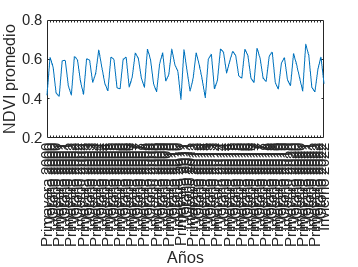

figure;

linea_tiempo = reshape(tabla_promedio',[],1);
linea_tiempo_desv = reshape(tabla_desvEst',[],1);

plot(linea_tiempo);
%title('NDVI promedio x estación');
xlabel('Años');
xticks(1:length(linea_tiempo));
xticklabels(lbl_ejex);
ylabel('NDVI promedio');
xlim([1 length(linea_tiempo)]);
ylim([0.2 0.8]);

% hold on
% 
% er=errorbar(1:length(linea_tiempo),linea_tiempo,linea_tiempo_desv); 
% er.Color = [0 0 0];                            
% er.LineStyle = 'none';  
% 
% hold off

exportgraphics(gca,"img/g_promedio_x_año_estacion_lt.png",'Resolution',300) 

### 5. Mostrar grafica de barras de una sola estación

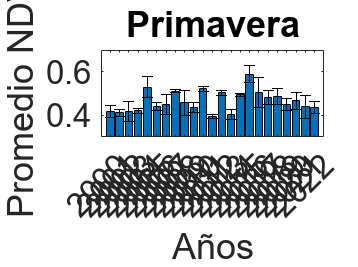

str_estacion = "Primavera";
estacion = lbl_estaciones==str_estacion;

figure;

bar(tabla_promedio(:,estacion));
title(str_estacion);
xlabel('Años');
xticks(1:length(tabla_promedio));
xticklabels(anios);
xtickangle(45);
ylabel('Promedio NDVI');
xlim([0 (length(tabla_promedio)+1)]);
ylim([0.3 0.7]);

hold on

er=errorbar(1:length(tabla_promedio),tabla_promedio(:,estacion),tabla_desvEst(:,estacion)); 
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off
ax = gca;
ax.FontSize=20; 

exportgraphics(gca,"img/g_promedio_x_año_"+str_estacion+"_lt.png",'Resolution',300) 

### 6. Mostrar el promedio de un año en particular

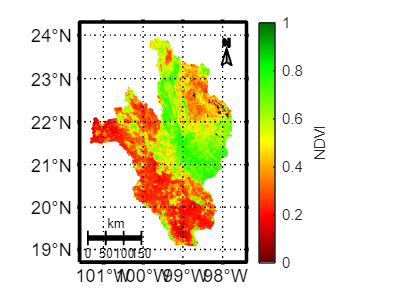

anio = 2013;
str_estacion = "Invierno";

estacion = find(lbl_estaciones==str_estacion);
indice = (4*(anio-2000))+estacion;

m_dibujar_mapa_ndvi(lon_mapa,lat_mapa,lon,lat,arr_ndvi(:,:,indice),"NDVI promedio de "+lbl_ejex(indice),0);
% %m_dibujar_otras_areas(dir_data);
% 
exportgraphics(gca,"img/m_promedio_"+lbl_ejex(indice)+".png",'Resolution',300) 